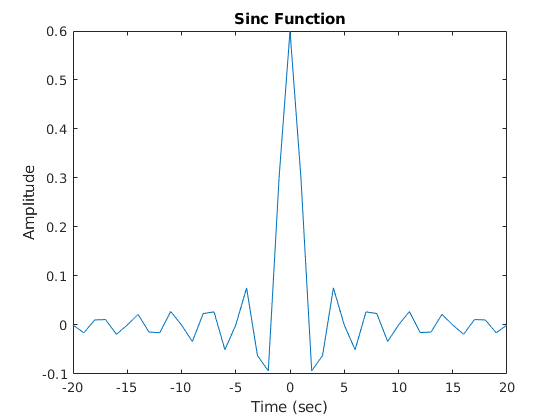

% Task 3
n=(-20:1:20);
fc=0.3;
y = 2*fc*sinc(n*2*fc);

plot(n,y);
xlabel('Time (sec)');
ylabel('Amplitude'); 
title('Sinc Function');

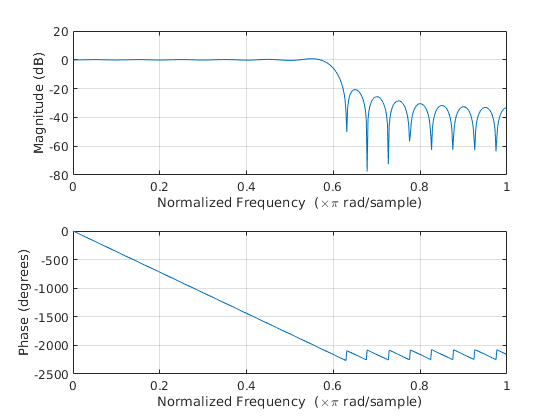


freqz(y)

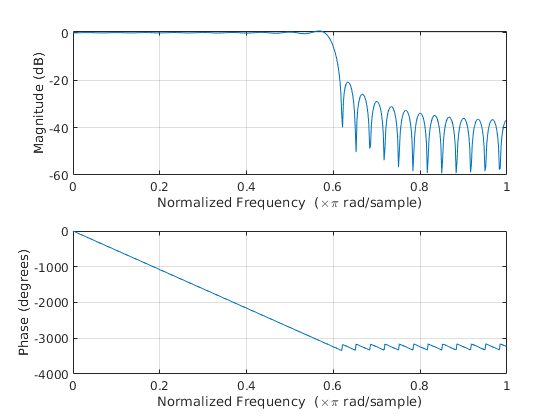


n=(-30:1:30);
y = 2*fc*sinc(n*2*fc);

freqz(y)

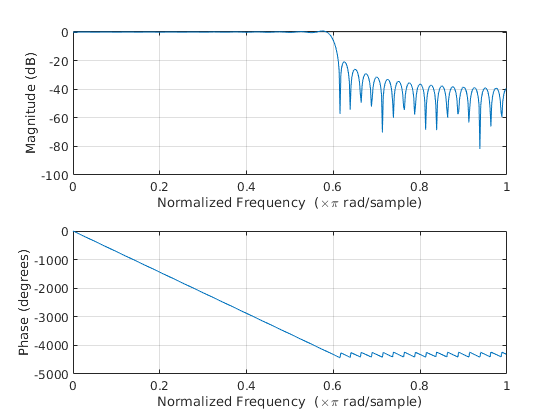



n=(-40:1:40);
y = 2*fc*sinc(n*2*fc);

freqz(y)

% Task 4
clear all
disp('Task 4')

Task 4


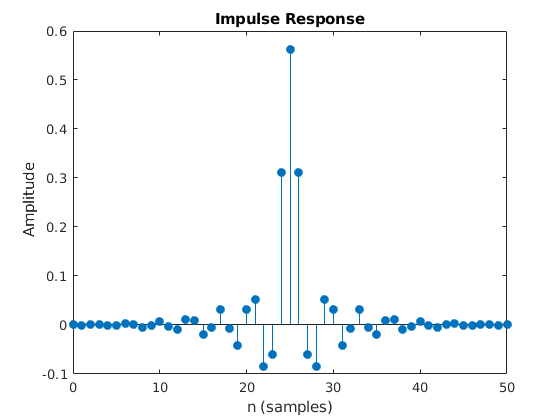

fp=4/16;
fs=5/16;

fc=(fp+fs)/2;

deltaf=fs-fp;

% we'll use hanning window 
N=3.1/deltaf;

% rounding above to nearest odd integer
N = (ceil((ceil(N)/2)+0.5)*2)-1;

y=fir1((N-1),2*fc,hanning(N));
impz(y)

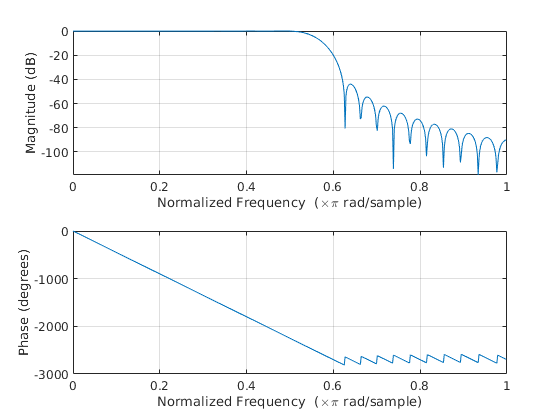

freqz(y)

% Task 5
disp("Task 5")

Task 5


clear all
load handel.mat
% a
disp("a")

a


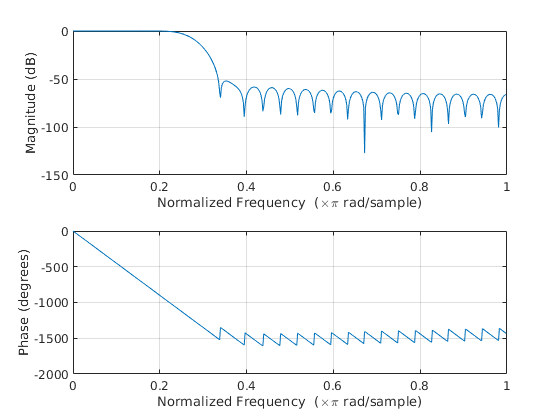

fp=1000/8192;
fs=1200/8192;
fc = (fp+fs)/2;
filter_a = fir1(50, 2*fc);
freqz(filter_a)

y_filtered_a = conv(filter_a,y);
soundsc(y_filtered_a)
pause(2)


% b
clear all
load handel.mat
disp("b")

b


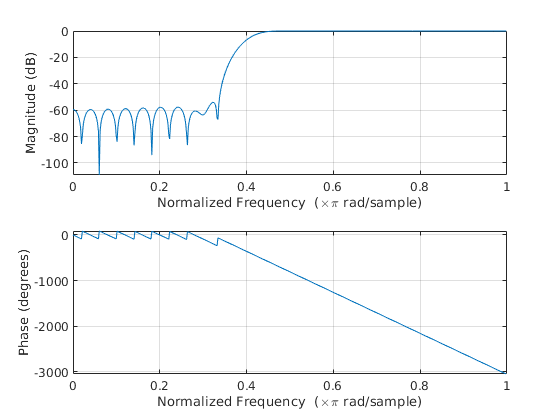

fp=1800/8192;
fs=1500/8192;
fc = (fp+fs)/2;
filter_b = fir1(50, 2*fc, 'high');
freqz(filter_b)

y_filtered_b = conv(filter_b,y);
soundsc(y_filtered_b)
pause(2)


% c
clear all
disp("c")

c


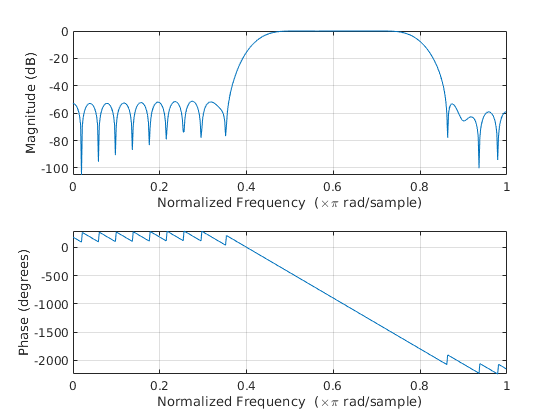

load handel.mat
fp=2000/8192;
fs=1500/8192;
w1 = (fp+fs)/2;
fp = 3000/8192;
fs= 3500/8192;
w2 = (fp+fs)/2;
wn= [2*w1, 2*w2];
filter_c = fir1(50, wn, 'bandpass');
freqz(filter_c)

y_filtered_c = conv(filter_c,y);
soundsc(y_filtered_c)
pause(2)


% d
disp("d")

d


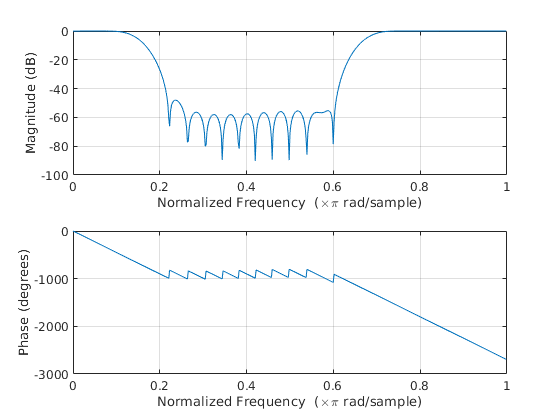

clear all
load handel.mat
fp=500/8192;
fs=750/8192;
w1 = (fp+fs)/2;
fp = 3000/8192;
fs= 2500/8192;
w2 = (fp+fs)/2;
wn= [2*w1, 2*w2];
filter_d = fir1(50, wn, 'stop');
freqz(filter_d)

y_filtered_d = conv(filter_d,y);
soundsc(y_filtered_d)
pause(2)

